Wczytywanie danych trenujących i czyszczenie zmiennych (najpewniej dzieje się tylko przy pełnym uruchomieniu)

clear variables
data = readtable("train_set.csv");

Wczytanie danych inflacji i przerobienie ich na tabelę

inflation = readtable("inflation/API_FP.CPI.TOTL.ZG_DS2_en_csv_v2_5454816.csv");
inflation = organize_inflation(inflation)

inflation = 63×266 table
             Aruba     Africa Eastern and Southern    Afghanistan    Africa Western and Central    Angola    Albania    Andorra    Arab World    United Arab Emirates    Argentina    Armenia    American Samoa    Antigua and Barbuda    Australia    Austria    Azerbaijan    Burundi      Belgium      Benin      Burkina Faso    Bangladesh    Bulgaria    Bahrain     Bahamas, The    Bosnia and Herzegovina    Belarus     Belize     Bermuda    Bolivia    Brazil    

idata = clear_data(data)

idata = 18895×20 table
    TERMIN_PLATNOSCI    CZY_CHLODNIA    MIN_CZAS_TRANSPORTU    MAX_CZAS_TRANSPORTU    LICZBA_ZALADUNKOW    LICZBA_ROZLADUNKOW    CALKOWITA_ODLEGLOSC    MAX_WAGA    TONOKILOMETRY    ODLEGLOSC_NA_PUSTO    CENA_PALIWA    ODSTEP_CZASOWY    ILE_DNI_TEMU    KLASTER    KOSZT     CZAS_REALIZACJI    SZEROKOSC_ZALADUNKU    DLUGOSC_ZALADUNKU    SZEROKOSC_ROZLADUNKU    DLUGOSC_ROZLADUNKU
    ________________    ____________    ___________________    ___________________    _________________    __________________    ___________________

cdata = divide_cluster(idata,2)

cdata = 1×92 cell array
    {3×20 table}    {3×20 table}    {9×20 table}    {2×20 table}    {2×20 table}    {3×20 table}    {11×20 table}    {2×20 table}    {12×20 table}    {2×20 table}    {26×20 table}    {4×20 table}    {2×20 table}    {3×20 table}    {5×20 table}    {3×20 table}    {2×20 table}    {10×20 table}    {8×20 table}    {2×20 table}    {4×20 table}    {2×20 table}    {31×20 table}    {3×20 table}    {3×20 table}    {3×20 table}    {5×20 table}    {3×20 table}    {2×20 table}    {3×20 table}    {4×20 table}    {137×20 table}    {2×20 table}    {2×20 table}    {2×20 table}    {4×20 table}    {2×20 table}    {66×20 table}    {43×20 table}    {3×20 table}    {4511×20 table}    {4×20 table}    {4×20 table}    {5×20 table}    {130×20 table}    {4×20 table}    {2×20 table}    {509×20 table}    {4×20 table}    {133×20 table}    {108×20 table}    {3×20 table}    {2×20 table}    {2×20 table}    {11×20 table}    {3×20 table}    {505×20 table}    {2×20 table}    {4×20 table}    {5×20

## Wybór klastra

% NAJCZĘŚCIEJ SPOTYKANE KLASTRY W TESTOWYM (JEDYNE WIĘCEJ NIŻ 4 PRÓBKI)
idata = cdata{73};  % klaster 378 - Polska
% idata = cdata{41};  % klaster 175 - Polska
% idata = cdata{57};  % klaster 270 - Polska
% idata = cdata{48};  % klaster 225 - Polska
% idata = cdata{51};  % klaster 237 - Polska
% idata.CALKOWITA_ODLEGLOSC = idata.CALKOWITA_ODLEGLOSC.*idata.CENA_PALIWA
% idata.KOSZT = idata.KOSZT./idata.CENA_PALIWA;

Korekta o inflacje ręczna zakładając, że wszystkie dane uczące mają 5 lat i są z Polski

% inflation = [1.81295156542681, 2.227478809383, 3.3744697261859, 5.05502704719268, 14.4294507575757];
% ii=1;
% for i=1:max(size(inflation))
%     ii = ii*(1+inflation(i)/100);
% end
% ii
% idata.KOSZT=idata.KOSZT*ii;

Korekta o inflacje liczona dla każdej próbki oddzielnie

idata = adjust4inflation(idata,inflation)

idata = 11866×20 table
    TERMIN_PLATNOSCI    CZY_CHLODNIA    MIN_CZAS_TRANSPORTU    MAX_CZAS_TRANSPORTU    LICZBA_ZALADUNKOW    LICZBA_ROZLADUNKOW    CALKOWITA_ODLEGLOSC    MAX_WAGA    TONOKILOMETRY    ODLEGLOSC_NA_PUSTO    CENA_PALIWA    ODSTEP_CZASOWY    ILE_DNI_TEMU    KLASTER    KOSZT     CZAS_REALIZACJI    SZEROKOSC_ZALADUNKU    DLUGOSC_ZALADUNKU    SZEROKOSC_ROZLADUNKU    DLUGOSC_ROZLADUNKU
    ________________    ____________    ___________________    ___________________    _________________    __________________    ___________________

summary(idata)

Variables:

    TERMIN_PLATNOSCI: 11866×1 double

        Values:

            Min       -10.444 
            Median         60 
            Max            90 

    CZY_CHLODNIA: 11866×1 double

        Values:

            Min          0    
            Median       1    
            Max          1    

    MIN_CZAS_TRANSPORTU: 11866×1 double

        Values:

            Min           0   
            Median        2   
            Max         234   

    MAX_CZAS_TRANSPORTU: 11866×1 double

        Values:

            Min           0   
            Median        2   
            Max         242   

    LICZBA_ZALADUNKOW: 11866×1 double

        Values:

            Min          1    
            Median       1    
            Max          3    

    LICZBA_ROZLADUNKOW: 11866×1 double

        Values:

            Min          1    
            Median       1    
            Max    

mean(idata.KOSZT)

ans = 344.2914

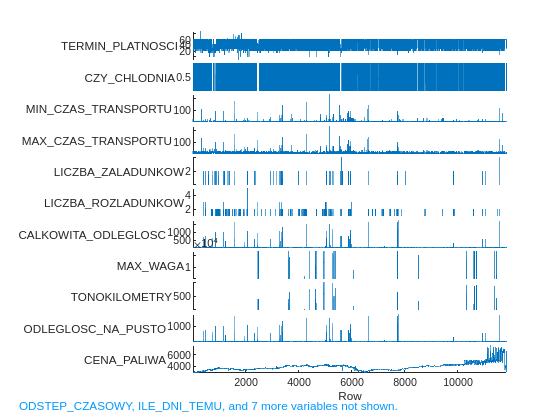

stackedplot(idata)

corrcoef([idata.KOSZT, idata.CALKOWITA_ODLEGLOSC, idata.TERMIN_PLATNOSCI, ...
    idata.CENA_PALIWA.*idata.CALKOWITA_ODLEGLOSC])

ans =     1.0000    0.8855    0.1304    0.8879
    0.8855    1.0000   -0.0723    0.9898
    0.1304   -0.0723    1.0000   -0.0692
    0.8879    0.9898   -0.0692    1.0000


corrcoef([idata.KOSZT, idata.MIN_CZAS_TRANSPORTU, idata.MAX_CZAS_TRANSPORTU])

ans =     1.0000    0.7383    0.3398
    0.7383    1.0000    0.5713
    0.3398    0.5713    1.0000


## Tutaj zmiana parametrów modelu

r = [
    0,
    10,
    15,
%     19,  % dziwne, w przedziale <19; 20) jest > 6k recordów
    20,
    35,
    50,
    100,
    200,
    300,
    400,
    500,
    600,
    700,
    800,
%     1000,
%     1300,
%     1600,
    max(idata.CALKOWITA_ODLEGLOSC)+1
];
[nidata, ranges, cls] = divide_data(idata,r);
m = Model(idata,r);
m = m.fit(1);

for i=1:cls
    p{i} = polyfit(nidata{i}.CALKOWITA_ODLEGLOSC, nidata{i}.KOSZT, 1);
end

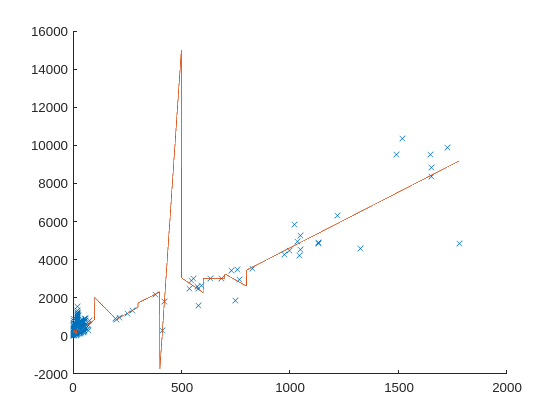

figure
hold on
% for i=1:cls
%     x = ranges{i}.min:1:ranges{i}.max;
%     plot(nidata{i}.CALKOWITA_ODLEGLOSC, nidata{i}.KOSZT, 'x')
% %     plot(x, polyval(p{i}, x))
%     plot(x, m.predict_many(x'))
% end
x = min(idata.CALKOWITA_ODLEGLOSC):max(idata.CALKOWITA_ODLEGLOSC);
plot(idata.CALKOWITA_ODLEGLOSC, idata.KOSZT, 'x')
plot(x, m.predict_many(x'))
hold off

for i=1:cls
    mae(nidata{i}.KOSZT, polyval(p{i}, nidata{i}.CALKOWITA_ODLEGLOSC))
    mae(nidata{i}.KOSZT, m.predict_many(nidata{i}.CALKOWITA_ODLEGLOSC))
end

ans = 105.7122

ans = 105.7122

ans = 40.3826

ans = 40.3826

ans = 62.1936

ans = 62.1936

ans = 68.0103

ans = 68.0103

ans = 66.5853

ans = 66.5853

ans = 180.2123

ans = 180.2123

ans = 5.1159e-13

ans = 5.1159e-13

ans = 2.7870

ans = 2.7870

ans = 0

ans = 0

ans = 1.0033e-11

ans = 1.0033e-11

ans = 288.5800

ans = 288.5800

ans = 2.2737e-13

ans = 2.2737e-13

ans = 532.3208

ans = 532.3208

ans = 942.0955

ans = 942.0955

mae(idata.KOSZT, m.predict_many(idata.CALKOWITA_ODLEGLOSC))

ans = 66.3664

Testy

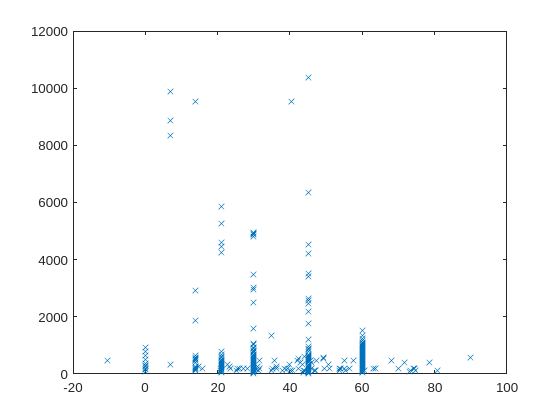

figure
plot(idata.TERMIN_PLATNOSCI, idata.KOSZT, 'x')

## Sprawdzenie na danych testowych

tdata = readtable("test_set.csv");
tidata = clear_data(tdata);
tcdata = divide_cluster(tidata,1)

tcdata = 1×15 cell array
    {4×20 table}    {3×20 table}    {1×20 table}    {1×20 table}    {1×20 table}    {1×20 table}    {1×20 table}    {1×20 table}    {1×20 table}    {64×20 table}    {1×20 table}    {39×20 table}    {14×20 table}    {45×20 table}    {442×20 table}


tidata = tidata(tidata.KLASTER == idata.KLASTER(1),:);
% tidata = tidata(tidata.KOSZT < 10000,:);  % do klastra 237, bo przy nim jeden przejazd nagle kosztuje 14k...
% tidata.CALKOWITA_ODLEGLOSC = tidata.CALKOWITA_ODLEGLOSC.*tidata.CENA_PALIWA
% tidata.KOSZT = tidata.KOSZT./tidata.CENA_PALIWA;
mean(tidata.KOSZT)

ans = 287.5467

mae(tidata.KOSZT, m.predict_many(tidata.CALKOWITA_ODLEGLOSC))

ans = 68.1370

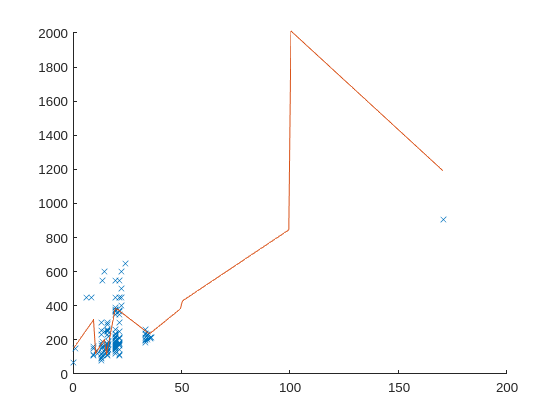

[tnidata, ranges, cls] = divide_data(tidata, r);
figure
hold on
% for i=1:cls
%     x = ranges{i}.min:1:ranges{i}.max;
%     plot(tnidata{i}.CALKOWITA_ODLEGLOSC, tnidata{i}.KOSZT, 'x')
% %     plot(x, polyval(p{i}, x))
%     plot(x, m.predict_many(x'))
% end
x = min(tidata.CALKOWITA_ODLEGLOSC):max(tidata.CALKOWITA_ODLEGLOSC);
plot(tidata.CALKOWITA_ODLEGLOSC, tidata.KOSZT, 'x')
plot(x, m.predict_many(x'))
hold off

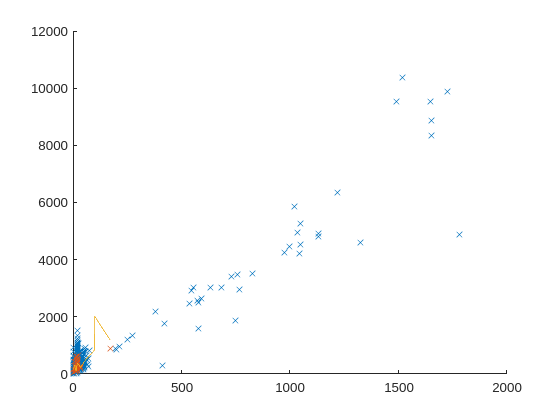

figure
hold on
plot(idata.CALKOWITA_ODLEGLOSC, idata.KOSZT, 'x')
plot(tidata.CALKOWITA_ODLEGLOSC, tidata.KOSZT, 'x')
plot(x, m.predict_many(x'))
hold off

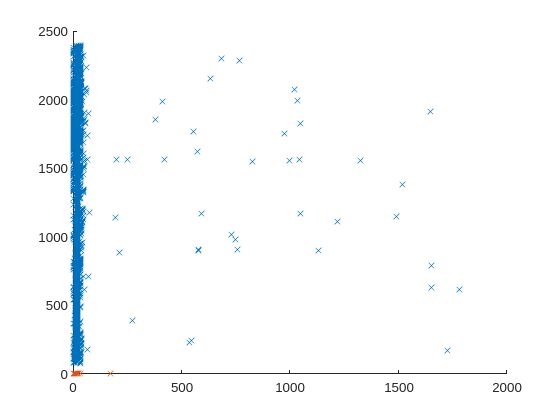

figure
hold on
plot(idata.CALKOWITA_ODLEGLOSC, idata.ILE_DNI_TEMU, 'x')
plot(tidata.CALKOWITA_ODLEGLOSC, tidata.ILE_DNI_TEMU, 'x')
hold off

for i=1:cls
    mae(tnidata{i}.KOSZT, polyval(p{i}, tnidata{i}.CALKOWITA_ODLEGLOSC))
end

ans = 151.5215

ans = 56.1143

ans = 59.9071

ans = 79.8118

ans = 29.3066

ans = NaN

ans = 286.5148

ans = NaN

ans = NaN

ans = NaN

ans = NaN

ans = NaN

ans = NaN

ans = NaN

diff = abs(nidata{1}.KOSZT - polyval(p{1}, nidata{1}.CALKOWITA_ODLEGLOSC));
mean(diff)

ans = 105.7122

median(diff)

ans = 82.9567

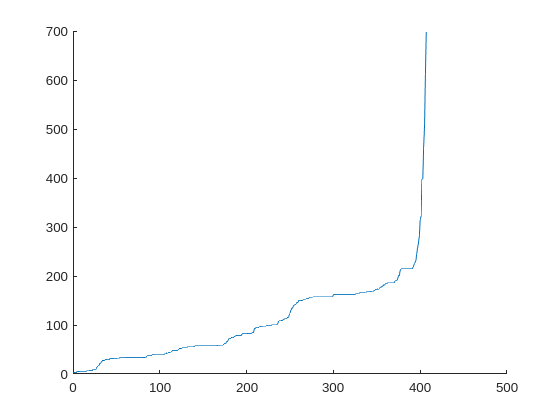

diff = sort(diff);
figure
hold on
plot(diff)
% plot(diff(1:1.7*10^4))
hold off

fidata = idata(abs(idata.KOSZT - polyval(p, idata.CALKOWITA_ODLEGLOSC)) < 1.9*10*3,:)

Error using polyval
Inputs must be floats, namely single or double.

plot(sort(abs(fidata.KOSZT - polyval(p, fidata.CALKOWITA_ODLEGLOSC))))
figure
hold on
plot(fidata.CALKOWITA_ODLEGLOSC, fidata.KOSZT, 'x')
plot(fidata.CALKOWITA_ODLEGLOSC, polyval(p, fidata.CALKOWITA_ODLEGLOSC))
hold off

tdata = readtable("test_set.csv");
tdata = tdata(tdata.KLASTER_ZALADUNKU == tdata.KLASTER_ROZLADUNKU,:);
mae(tdata.KOSZT, polyval(p, tdata.CALKOWITA_ODLEGLOSC))
dif = abs(tdata.KOSZT - polyval(p, tdata.CALKOWITA_ODLEGLOSC));
mean(dif)
median(dif)
figure
plot(tdata.CALKOWITA_ODLEGLOSC, tdata.KOSZT, 'x')